%% Calculations for the enhancement of gyromagnetic ratio. 

% This is based on the 2 papers below. Check references for the relevant
% info.
% The 3 main references for this are:
% 1. Mo Chen, Masashi Hirose, Paola Cappellaro, et al. Measurement of transverse hyperfine interaction by forbidden transitions. Physical Review B, 92(2):020101, 2015.
% 2. S Sangtawesin, CA McLellan, BA Myers, AC Bleszynski Jayich, DD Awschalom, and Jason R Petta. Hyperfine-enhanced gyromagnetic ratio of a nuclear spin in diamond. New Journal of Physics, 18(8):083016, 2016
% 3. Xingyu Gao, Sumukh Vaidya, Kejun Li, Peng Ju, Boyang Jiang, Zhujing Xu, Andres E. Llacsahuanga Allcca et al. "Nuclear spin polarization and control in hexagonal boron nitride.” Nature Materials 21, no. 9 (2022): 1024-1028. 

% Here I derive the equation S.6 from the Mo Chen (2015) paper. 

% We have a spin-1/2 electron and spin-1/2 nucleus coupled to an external
% magnetic field and to each other via hyperfine interaction. The electron
% spin has no ZFS and nucleus has no Quadrupole term.

% All Spin-1 operators
I3=eye(3);
Sz=zeros(3); Sz(1,1)=1; Sz(3,3)=-1;
Splus=zeros(3); Splus(1,2)=sqrt(2);Splus(2,3)=sqrt(2);
Sminus=zeros(3); Sminus(2,1)=sqrt(2);Sminus(3,2)=sqrt(2);
Sx=.5*(Splus+Sminus);
Sy=.5*1j*(Sminus-Splus);

% All spin-1/2 operators
I2=eye(2);
Iplus=[0 1; 0 0];
Iminus=[0 0; 1 0];
Iy=.5*1j*(Iminus-Iplus);
Ix=.5*(Iplus+Iminus);
% Iz=.5*[1 0; 0 -1];
Iz=.5*[1 0; 0 -1];

syms gamma_e gamma_n B_z A_para A_perp B_1 omega t

nu = sym('nu', 'real');
% nu_m = sym('nu_m', 'real');

H_para=gamma_e*B_z*kron(Iz,I2)+gamma_n*B_z*kron(I2,Iz)+A_para*kron(Iz,Iz)

$$H\_para = \left(\begin{array}{cccc} \frac{A_{\mathrm{para}}}{4}+\frac{B_{z}\,\gamma_{e}}{2}+\frac{B_{z}\,\gamma_{n}}{2} & 0 & 0 & 0\\ 0 & \frac{B_{z}\,\gamma_{e}}{2}-\frac{A_{\mathrm{para}}}{4}-\frac{B_{z}\,\gamma_{n}}{2} & 0 & 0\\ 0 & 0 & \frac{B_{z}\,\gamma_{n}}{2}-\frac{B_{z}\,\gamma_{e}}{2}-\frac{A_{\mathrm{para}}}{4} & 0\\ 0 & 0 & 0 & \frac{A_{\mathrm{para}}}{4}-\frac{B_{z}\,\gamma_{e}}{2}-\frac{B_{z}\,\gamma_{n}}{2} \end{array}\right)$$

H_perp=A_perp*(kron(Ix,Ix)+kron(Iy,Iy))

$$H\_perp = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & \frac{A_{\mathrm{perp}}}{2} & 0\\ 0 & \frac{A_{\mathrm{perp}}}{2} & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

H_tot=H_para+H_perp

$$H\_tot = \left(\begin{array}{cccc} \frac{A_{\mathrm{para}}}{4}+\frac{B_{z}\,\gamma_{e}}{2}+\frac{B_{z}\,\gamma_{n}}{2} & 0 & 0 & 0\\ 0 & \frac{B_{z}\,\gamma_{e}}{2}-\frac{A_{\mathrm{para}}}{4}-\frac{B_{z}\,\gamma_{n}}{2} & \frac{A_{\mathrm{perp}}}{2} & 0\\ 0 & \frac{A_{\mathrm{perp}}}{2} & \frac{B_{z}\,\gamma_{n}}{2}-\frac{B_{z}\,\gamma_{e}}{2}-\frac{A_{\mathrm{para}}}{4} & 0\\ 0 & 0 & 0 & \frac{A_{\mathrm{para}}}{4}-\frac{B_{z}\,\gamma_{e}}{2}-\frac{B_{z}\,\gamma_{n}}{2} \end{array}\right)$$

As can be seen here the only states being mixed are |+,-> and |-,+>. We do a simple rotation matrix to make the off diagonal terms zero and find the angle of rotation. 

Applying the same rotation transform under the RF Hamiltonian will give the enhancement for different sublevels. 

U_rot=[cos(nu) sin(nu); -sin(nu) cos(nu)];
U_r=sym(eye(4));
U_r(2:3,2:3)=U_rot

$$U\_r = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(\nu \right) & \sin\left(\nu \right) & 0\\ 0 & -\sin\left(\nu \right) & \cos\left(\nu \right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_tot_rot=U_r*H_tot*U_r'

$$H\_tot\_rot = \begin{array}{l} \left(\begin{array}{cccc} \frac{A_{\mathrm{para}}}{4}+\frac{B_{z}\,\gamma_{e}}{2}+\frac{B_{z}\,\gamma_{n}}{2} & 0 & 0 & 0\\ 0 & -\cos\left(\nu \right)\,\sigma_{1}-\sin\left(\nu \right)\,\sigma_{2} & \sin\left(\nu \right)\,\sigma_{1}-\cos\left(\nu \right)\,\sigma_{2} & 0\\ 0 & \cos\left(\nu \right)\,\sigma_{4}-\sin\left(\nu \right)\,\sigma_{3} & -\cos\left(\nu \right)\,\sigma_{3}-\sin\left(\nu \right)\,\sigma_{4} & 0\\ 0 & 0 & 0 & \frac{A_{\mathrm{para}}}{4}-\frac{B_{z}\,\gamma_{e}}{2}-\frac{B_{z}\,\gamma_{n}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\nu \right)\,\sigma_{7}-\sigma_{6}\\ \sigma_{2}=\sin\left(\nu \right)\,\sigma_{5}-\sigma_{8}\\ \sigma_{3}=\cos\left(\nu \right)\,\sigma_{5}+\sigma_{6}\\ \sigma_{4}=\sin\left(\nu \right)\,\sigma_{7}+\sigma_{8}\\ \sigma_{5}=\frac{A_{\mathrm{para}}}{4}+\frac{B_{z}\,\gamma_{e}}{2}-\frac{B_{z}\,\gamma_{n}}{2}\\ \sigma_{6}=\frac{A_{\mathrm{perp}}\,\sin\left(\nu \right)}{2}\\ \sigma_{7}=\frac{A_{\mathrm{para}}}{4}-\frac{B_{z}\,\gamma_{e}}{2}+\frac{B_{z}\,\gamma_{n}}{2}\\ \sigma_{8}=\frac{A_{\mathrm{perp}}\,\cos\left(\nu \right)}{2} \end{array}$$

H_tot_rot(2,3)

$$ans = \sin\left(\nu \right)\,\left(\cos\left(\nu \right)\,\left(\frac{A_{\mathrm{para}}}{4}-\frac{B_{z}\,\gamma_{e}}{2}+\frac{B_{z}\,\gamma_{n}}{2}\right)-\frac{A_{\mathrm{perp}}\,\sin\left(\nu \right)}{2}\right)-\cos\left(\nu \right)\,\left(\sin\left(\nu \right)\,\left(\frac{A_{\mathrm{para}}}{4}+\frac{B_{z}\,\gamma_{e}}{2}-\frac{B_{z}\,\gamma_{n}}{2}\right)-\frac{A_{\mathrm{perp}}\,\cos\left(\nu \right)}{2}\right)$$

H_tot_rot(3,2)

$$ans = \cos\left(\nu \right)\,\left(\sin\left(\nu \right)\,\left(\frac{A_{\mathrm{para}}}{4}-\frac{B_{z}\,\gamma_{e}}{2}+\frac{B_{z}\,\gamma_{n}}{2}\right)+\frac{A_{\mathrm{perp}}\,\cos\left(\nu \right)}{2}\right)-\sin\left(\nu \right)\,\left(\cos\left(\nu \right)\,\left(\frac{A_{\mathrm{para}}}{4}+\frac{B_{z}\,\gamma_{e}}{2}-\frac{B_{z}\,\gamma_{n}}{2}\right)+\frac{A_{\mathrm{perp}}\,\sin\left(\nu \right)}{2}\right)$$

Equating the above expressions both to 0 yields the same value of tan(2*nu)=A_perp/(B_z*(gamma_e-gamma_n)). This means this is consistent with the paper's notation. 

Now I calculate the enhancement factors for the various spin sublevels under the same transformation.

H_rf=B_1*(gamma_e*kron(Ix,I2)+gamma_n*kron(I2,Ix))

$$H\_rf = \left(\begin{array}{cccc} 0 & \frac{B_{1}\,\gamma_{n}}{2} & \frac{B_{1}\,\gamma_{e}}{2} & 0\\ \frac{B_{1}\,\gamma_{n}}{2} & 0 & 0 & \frac{B_{1}\,\gamma_{e}}{2}\\ \frac{B_{1}\,\gamma_{e}}{2} & 0 & 0 & \frac{B_{1}\,\gamma_{n}}{2}\\ 0 & \frac{B_{1}\,\gamma_{e}}{2} & \frac{B_{1}\,\gamma_{n}}{2} & 0 \end{array}\right)$$

H_rf_rot=U_r*H_rf*U_r'

$$H\_rf\_rot = \begin{array}{l} \left(\begin{array}{cccc} 0 & \sigma_{3} & \sigma_{2} & 0\\ \sigma_{3} & 0 & 0 & \sigma_{4}\\ \sigma_{2} & 0 & 0 & \sigma_{1}\\ 0 & \sigma_{4} & \sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{B_{1}\,\gamma_{n}\,\cos\left(\nu \right)}{2}-\frac{B_{1}\,\gamma_{e}\,\sin\left(\nu \right)}{2}\\ \sigma_{2}=\frac{B_{1}\,\gamma_{e}\,\cos\left(\nu \right)}{2}-\frac{B_{1}\,\gamma_{n}\,\sin\left(\nu \right)}{2}\\ \sigma_{3}=\frac{B_{1}\,\gamma_{n}\,\cos\left(\nu \right)}{2}+\frac{B_{1}\,\gamma_{e}\,\sin\left(\nu \right)}{2}\\ \sigma_{4}=\frac{B_{1}\,\gamma_{e}\,\cos\left(\nu \right)}{2}+\frac{B_{1}\,\gamma_{n}\,\sin\left(\nu \right)}{2} \end{array}$$

Equating this equal to H_n+H_e, H_n can be written as (alpha_plus|+><+|+alpha_minus|-><-|)I_x

Hence sigma_3 and sigma_1 above are enhancement factors for |+> and |-> respectively.

c_nu=sqrt(.5+.5*B_z*(gamma_e-gamma_n)/sqrt(A_perp^2+B_z^2*(gamma_e-gamma_n)^2))

$$c\_nu = \sqrt{\frac{B_{z}\,\left(\gamma_{e}-\gamma_{n}\right)}{2\,\sqrt{{A_{\mathrm{perp}}}^{2}+{B_{z}}^{2}\,{\left(\gamma_{e}-\gamma_{n}\right)}^{2}}}+\frac{1}{2}}$$

s_nu=sqrt(.5-.5*B_z*(gamma_e-gamma_n)/sqrt(A_perp^2+B_z^2*(gamma_e-gamma_n)^2))

$$s\_nu = \sqrt{\frac{1}{2}-\frac{B_{z}\,\left(\gamma_{e}-\gamma_{n}\right)}{2\,\sqrt{{A_{\mathrm{perp}}}^{2}+{B_{z}}^{2}\,{\left(\gamma_{e}-\gamma_{n}\right)}^{2}}}}$$

alpha_plus=c_nu+gamma_e*s_nu/gamma_n

$$alpha\_plus = \sqrt{\frac{B_{z}\,\left(\gamma_{e}-\gamma_{n}\right)}{2\,\sqrt{{A_{\mathrm{perp}}}^{2}+{B_{z}}^{2}\,{\left(\gamma_{e}-\gamma_{n}\right)}^{2}}}+\frac{1}{2}}+\frac{\gamma_{e}\,\sqrt{\frac{1}{2}-\frac{B_{z}\,\left(\gamma_{e}-\gamma_{n}\right)}{2\,\sqrt{{A_{\mathrm{perp}}}^{2}+{B_{z}}^{2}\,{\left(\gamma_{e}-\gamma_{n}\right)}^{2}}}}}{\gamma_{n}}$$

alpha_minus=c_nu-gamma_e*s_nu/gamma_n

$$alpha\_minus = \sqrt{\frac{B_{z}\,\left(\gamma_{e}-\gamma_{n}\right)}{2\,\sqrt{{A_{\mathrm{perp}}}^{2}+{B_{z}}^{2}\,{\left(\gamma_{e}-\gamma_{n}\right)}^{2}}}+\frac{1}{2}}-\frac{\gamma_{e}\,\sqrt{\frac{1}{2}-\frac{B_{z}\,\left(\gamma_{e}-\gamma_{n}\right)}{2\,\sqrt{{A_{\mathrm{perp}}}^{2}+{B_{z}}^{2}\,{\left(\gamma_{e}-\gamma_{n}\right)}^{2}}}}}{\gamma_{n}}$$

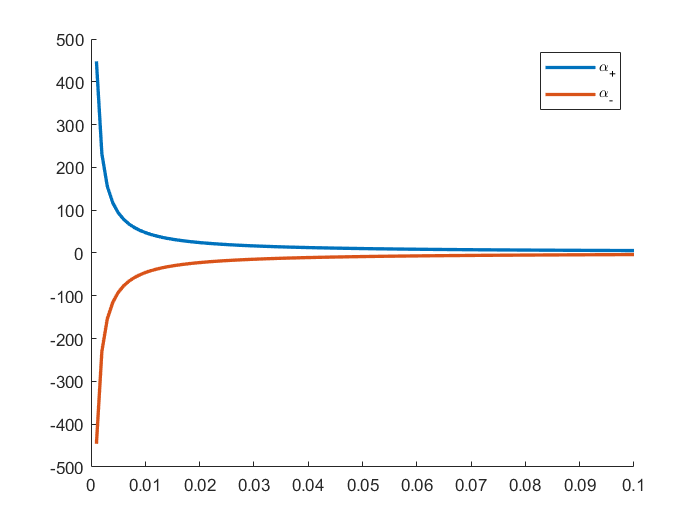

B=[1e-3:1e-3:100e-3];
alpha_p=zeros(length(B),1);
alpha_m=zeros(length(B),1);
for i=1:length(B)
    alpha_p(i)=subs(alpha_plus,[B_z,gamma_e,gamma_n,A_perp],[B(i), 28e9, 10.7e6, 10e6]);
    alpha_m(i)=subs(alpha_minus,[B_z,gamma_e,gamma_n,A_perp],[B(i), 28e9, 10.7e6, 10e6]);
end
figure(1);
hold on;
plot(B,alpha_p, 'LineWidth',2);
plot(B,alpha_m, 'LineWidth',2);
legend('\alpha_+','\alpha_-');